# Models that are a linear combination of basis functions

Linear regression and polynomial regression are examples of the class of models where the model weights appear linearly. This class of models has the form of a linear combination of basis functions


$$f(x) = w_0 \phi_0(x) + w_1 \phi_1(x) + \cdots + w_m \phi_m(x)$$


where the $\phi_j(x)$ are basis functions and $x$ can be scalar or vector. Different models can be created by choosing different sets of basis functions. Here, we give an example using Gaussian basis functions.

Note that it is usually difficult to know how to choose the basis functions for a particular regression problem. The more important reason for us to introduce the concept of linear combination of basis function models is that many more advanced machine learning models, as we will see later, can be interpreted as such linear combinations.

Gaussian basis functions for a scalar $x$ have the form


$$\phi_j(x) = \exp \big( -\frac{1}{2s^2} (x - \mu_j)^2 \big)$$


where $s$ is the Gaussian width. We will try three different values of $s$. Each basis function has the shape of a Gaussian with a different center $\mu_j$.

The true function is one cycle of $sin(x)$. We'll generate $n$ observations, with x-values equally-spaced, with noise from a known noise distribution.

% generate synthetic data
rng(0);
fun = @(x) sin(2*pi*x); % true function
sigma2 = 0.1;           % noise variance
n = 10;                 % number of observations
x = (0:1/(n-1):1)';
y = fun(x) + sqrt(sigma2)*randn(size(x));

We will use four equally-spaced basis functions. You can try to see the effect when you increase or decrease the number of basis functions.

% define Gaussian basis functions with uniformly spaced centers
num_func = 4;
delta = 1/(num_func+1);
centers = delta:delta:1-delta;

We will compute models using three different Gaussian widths. The models (thick black curves) will be plotted along with the true function (thick blue curve) and the basis functions (thin curves) that comprise the each model. The data is also plotted (red dots).

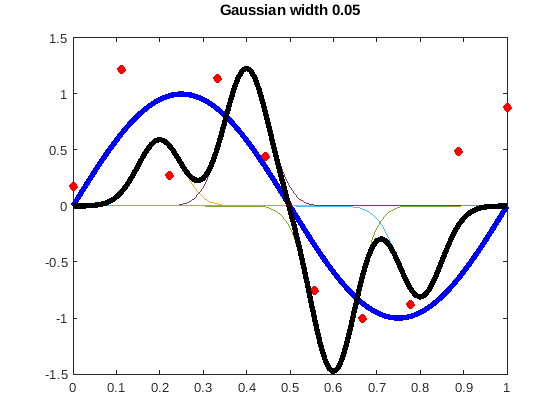

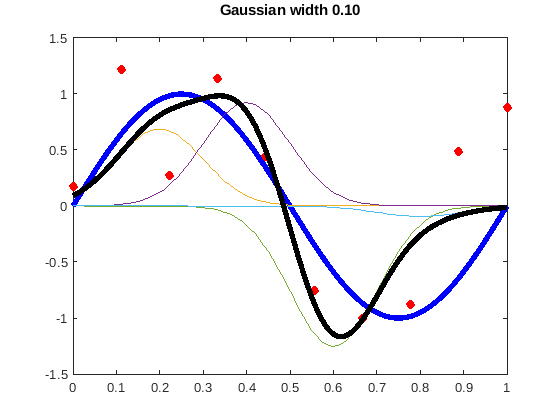

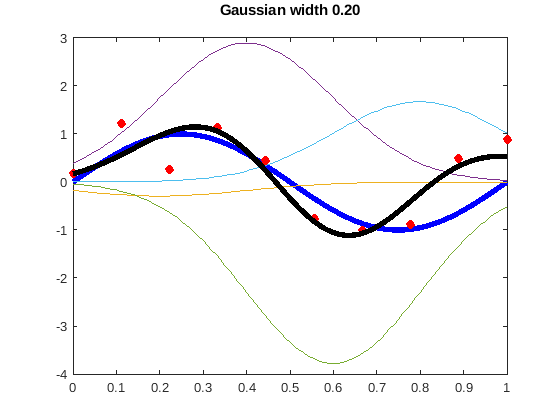

% try different values of Gaussian width
for s = [.05 .1 .2]
  % define Phi matrix
  Phi = zeros(n,num_func);
  for i = 1:n
  for j = 1:num_func
    Phi(i,j) = exp(-0.5/(s*s) * (x(i) - centers(j))^2);
  end
  end
  
  % compute model weights
  w = Phi\y;
  
  % plot true function and the data
  xx = 0:.01:1;
  figure
  plot(xx, fun(xx), 'b-', 'linewidth', 4);
  hold on
  plot(x, y, 'ro', 'markerfacecolor', 'r');
  
  % plot each weighted basis function 
  totfun = zeros(size(xx));
  for j = 1:num_func
    b = w(j) * exp(-0.5/(s*s) * (xx - centers(j)).^2);
    plot(xx, b);
    totfun = totfun + b;
  end
  
  % plot linear combination of basis functions
  plot(xx, totfun, 'k-', 'linewidth', 4);
  title(sprintf('Gaussian width %.2f\n', s));
end

Observe that $s=0.05$ give Gaussian basis functions that are too narrow to adequately cover the $x$ values. For $s=0.20$, the model (black curve) is quite smooth, but the basis function weights are also large (the basis functions have large magnitude values, and are summed to get the relatively small magnitude values of the model).